# Strategy IX command file

Source output rate

load('failure_rate.mat','failure_rate');
MTBF = 1./failure_rate; % 5=N of components % From Schedule statistics
MTBF_h = MTBF.*8544/WT_n; % MTBF, T in hours

## SINGLE USE CODE

soi = 1;
yoi = 1;
%
i = yoi;
j = soi;
% Load data
load('Failure_data_index.mat');
load('Failure_events_index.mat');
load('Schedule_data_index.mat');
soi = 1;
yoi = 1;
%
i = yoi;
j = soi;
clear Failure_events
clear Failure_data
clear Schedule_data
Failure_data = Failure_data_index(yoi,soi);
Failure_events = Failure_events_index(yoi,soi);
Schedule_data = Schedule_data_index(yoi,soi);
% Open model
open('Supply_Chain_III.slx');

## Data generator

if true
    load('Failure_data_index.mat');
    load('Failure_events_index.mat');
    load('Schedule_data_index.mat');
    for j = 1:3 % Series !!!
        soi = j;
        for i = 1:20 % Years
            yoi = i;
            Failure_data = Failure_data_index(i,j);
            Failure_events = Failure_events_index(i,j);
            Schedule_data = Schedule_data_index(i,j);
            sim('Supply_Chain_III.slx');
            inventory_level_island_index(i,j) = {inventory_level_island};
            inventory_level_LW_index(i,j) = {inventory_level_LW};
            JIT_performance(i,3*(j-1)+(1:3)) = [{com_arrivals} {com_caller} {com_released}];
            n_components_in_sc_index(i,j) = {n_comps_in_sc};
            [i j]
        end
    end
    save('inventory_level_island_index.mat','inventory_level_island_index');
    save('inventory_level_LW_index.mat','inventory_level_LW_index');
    save('JIT_performance.mat','JIT_performance');
    save('n_components_in_sc_index.mat','n_components_in_sc_index');
end

ans =      1     1


ans =      2     1


ans =      3     1


ans =      4     1


ans =      5     1


ans =      6     1


ans =      7     1


ans =      8     1


ans =      9     1


ans =     10     1


ans =     11     1


ans =     12     1


ans =     13     1


ans =     14     1


ans =     15     1


ans =     16     1


ans =     17     1


ans =     18     1


ans =     19     1


ans =     20     1


ans =      1     2


ans =      2     2


ans =      3     2


ans =      4     2


ans =      5     2


ans =      6     2


ans =      7     2


ans =      8     2


ans =      9     2


ans =     10     2


ans =     11     2


ans =     12     2


ans =     13     2


ans =     14     2


ans =     15     2


ans =     16     2


ans =     17     2


ans =     18     2


ans =     19     2


ans =     20     2


ans =      1     3


ans =      2     3


ans =      3     3


ans =      4     3


ans =      5     3


ans =      6     3


ans =      7     3


ans =      8     3


ans =      9     3


ans =     10     3


ans =     11     3


ans =     12     3


ans =     13     3


ans =     14     3


ans =     15     3


ans =     16     3


ans =     17     3


ans =     18     3


ans =     19     3


ans =     20     3


## Performance output

NR OF PARTS IN SC

r = 20

c = 3

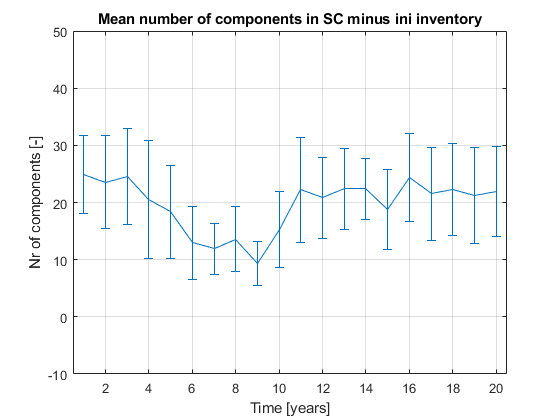

if true
    load('n_components_in_sc_index.mat')
    [r c] = size(n_components_in_sc_index)
    for i = 1:r
        for j = 1:c
            NOC = cell2mat(n_components_in_sc_index(i,j));
            mjNOC(j) = mean(NOC);
            vjNOC(j) = var(NOC);
        end
        mNOC(i) = mean(mjNOC);
        vNOC(i) = sqrt(sum(vjNOC)/c);
    end
    figure();
    errorbar([1:20],mNOC,vNOC);
    title('Mean number of components in SC minus ini inventory')
    xlabel('Time [years]')
    ylabel('Nr of components [-]')
    ylim([-10,50])
    xlim([0.5,20.5])
    grid on
end

Inventory

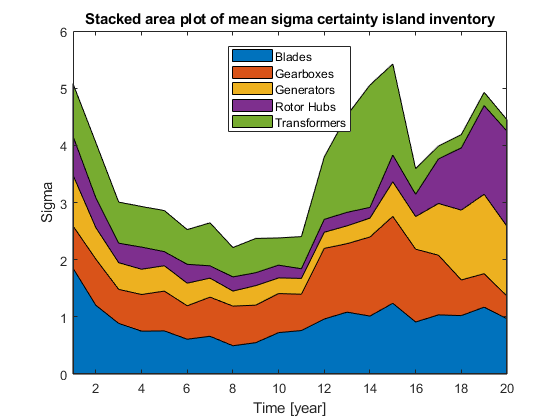

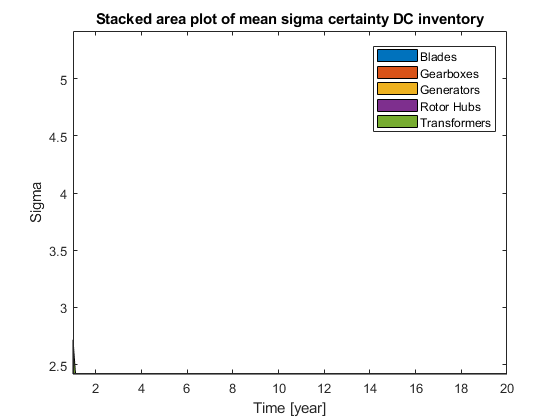

if true % Performance of inventory levels
    load('inventory_level_island_index.mat')
    load('inventory_level_LW_index.mat')
    [r c] = size(inventory_level_island_index);
    for i = 1:r
        for j = 1:c
        ILI = cell2mat(transpose(inventory_level_island_index(i,j)));
        inv_var_island(j,1:5) = var(ILI);
        
        ILLW = cell2mat(transpose(inventory_level_LW_index(i,j)));
        inv_var_localwarehouse(j,1:5) = var(ILLW);
        
        end
        inv_island_sigma(i,1:5) = sqrt(sum(inv_var_island)./3);
        inv_localwarehouse_sigma(i,1:5) = sqrt(sum(inv_var_localwarehouse)./3);
    end
    figure()
    area(inv_island_sigma)
    title('Stacked area plot of mean sigma certainty island inventory')
    xlabel('Time [year]')
    ylabel('Sigma')
    legend({'Blades','Gearboxes','Generators','Rotor Hubs','Transformers'},'Location','best')
    xlim([1 20])
    
    figure()
    area(inv_localwarehouse_sigma)
    title('Stacked area plot of mean sigma certainty DC inventory')
    xlabel('Time [year]')
    ylabel('Sigma')
    legend({'Blades','Gearboxes','Generators','Rotor Hubs','Transformers'},'Location','best')
    xlim([1 20])
end

## JIT Performance

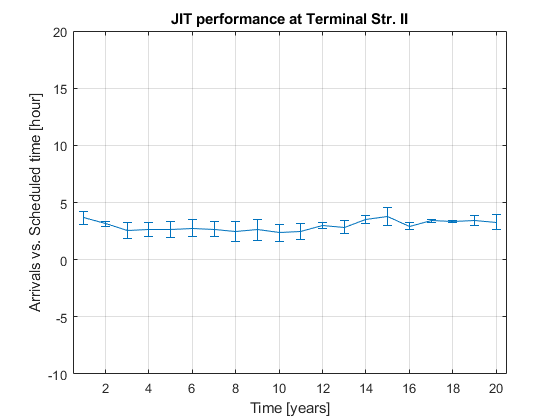

if true
    load('JIT_performance.mat')
    [r c] = size(JIT_performance);
    for i = 1:r
        for j = 1:(c/3)
            Arrivals = cell2mat(JIT_performance(i,3*j-2));
            Triggers = cell2mat(JIT_performance(i,3*j-1));
            Departures = cell2mat(JIT_performance(i,3*j));
            for h = 1:length(Arrivals)
                Arrivals_t = sum(Arrivals(h,:));
                Triggers_t = sum(Triggers(h,:));
                Departures_t = sum(Departures(h,:));
                if Arrivals_t >= Triggers_t
                    Perf(h,j) = Arrivals_t - Triggers_t;
                elseif Triggers_t > Departures_t
                    Perf(h,j) = Triggers_t - Departures_t;
                end
            end
        end
        Perf_t = sum(Perf) ./ sum(Perf~=0);
        Perf_m(i) = mean(Perf_t);
        Perf_s(i) = std(Perf_t);
    end
    figure();
    errorbar([1:20],Perf_m,Perf_s);
    title('JIT performance at Terminal Str. II')
    xlabel('Time [years]')
    ylabel('Arrivals vs. Scheduled time [hour]')
    ylim([-10,20])
    xlim([0.5,20.5])
    grid on
end

## The SC III optimizer

if true
    line = 1;
    load('Failure_data_index.mat');
    load('Failure_events_index.mat');
    load('Schedule_data_index.mat');
    
    clear Failure_e vents
    clear Failure_data
    clear Schedule_data
    for i = 11:20 % 20
        yoi = i;
        for AT = 1:5 % 5
            Transfers = [3 4 6 12 24];
            n_AT = Transfers(AT);
            
            for n_R = 1:20 % 20
                for j = 1:3 % 3
                    soi = j;
                    Failure_data = Failure_data_index(i,j);
                    Failure_events = Failure_events_index(i,j);
                    sim('Schedule_generator.slx');
                    Schedule_array = Schedule_data.Data;
                    for h = 1:length(Schedule_array)
                        if Schedule_array(h,6) ~= 0
                            row = Schedule_array(h,:);
                            for col = 1:6
                                if row(col) ~= 0
                                    Schedule_array(h+1,col) = 0;
                                    Schedule_array(h+2,col) = row(col) - 1;
                                end
                            end
                        end
                    end
                    % All non-zero to 1
                    [l m] = size(Schedule_array);
                    for r = 1:l
                        for c = 1:m
                            if Schedule_array(r,c) ~= 0
                                Schedule_array(r,c) = 1;
                            end
                        end
                    end
                    Schedule_data = timeseries(Schedule_array);
                    
                    sim('Supply_Chain_III.slx');
                    inventory_level_island_index(i,j) = {inventory_level_island};
                    JIT_performance(i,3*(j-1)+(1:3)) = [{com_arrivals} {com_caller} {com_released}];
                    
                end
                [r c] = size(inventory_level_island_index);
                
                for j = 1:c
                    ILI = cell2mat(transpose(inventory_level_island_index(i,j)));
                    inv_var_island(j,1:5) = var(ILI);
                end
                inv_island_sigma(1,1:5) = sqrt(sum(inv_var_island)./3);
                
                [r c] = size(JIT_performance);
                for j = 1:(c/3)
                    Arrivals = cell2mat(JIT_performance(i,3*j-2));
                    Triggers = cell2mat(JIT_performance(i,3*j-1));
                    Departures = cell2mat(JIT_performance(i,3*j));
                    for h = 1:length(Arrivals)
                        Arrivals_t = sum(Arrivals(h,:));
                        Triggers_t = sum(Triggers(h,:));
                        Departures_t = sum(Departures(h,:));
                        if Arrivals_t >= Triggers_t
                            Perf(h,j) = Arrivals_t - Triggers_t;
                        elseif Triggers_t > Departures_t
                            Perf(h,j) = Triggers_t - Departures_t;
                        end
                    end
                end
                Perf_t = sum(Perf) ./ sum(Perf~=0);
                Perf_m = mean(Perf_t);
                Perf_s = std(Perf_t);
                OPTI_DATA(line,:) = [i n_R n_AT Perf_s inv_island_sigma];
                 line
                line = line + 1;
            end
        end
    end
    save('inventory_level_island_index.mat','inventory_level_island_index');
    save('JIT_performance.mat','JIT_performance');
end

line = 1

line = 2

line = 3

line = 4

line = 5

line = 6

line = 7

line = 8

line = 9

line = 10

line = 11

line = 12

line = 13

line = 14

line = 15

line = 16

line = 17

line = 18

line = 19

line = 20

line = 21

line = 22

line = 23

line = 24

line = 25

line = 26

line = 27

line = 28

line = 29

line = 30

line = 31

line = 32

line = 33

line = 34

line = 35

line = 36

line = 37

line = 38

line = 39

line = 40

line = 41

line = 42

line = 43

line = 44

line = 45

line = 46

line = 47

line = 48

line = 49

line = 50

line = 51

line = 52

line = 53

line = 54

line = 55

line = 56

line = 57

line = 58

line = 59

line = 60

line = 61

line = 62

line = 63

line = 64

line = 65

line = 66

line = 67

line = 68

line = 69

line = 70

line = 71

line = 72

line = 73

line = 74

line = 75

line = 76

line = 77

line = 78

line = 79

line = 80

line = 81

line = 82

line = 83

line = 84

line = 85

line = 86

line = 87

line = 88

line = 89

line = 90

line = 91

line = 92

line = 93

line = 94

line = 95

line = 96

line = 97

line = 98

line = 99

line = 100

line = 101

line = 102

line = 103

line = 104

line = 105

line = 106

line = 107

line = 108

line = 109

line = 110

line = 111

line = 112

line = 113

line = 114

line = 115

line = 116

line = 117

line = 118

line = 119

line = 120

line = 121

line = 122

line = 123

line = 124

line = 125

line = 126

line = 127

line = 128

line = 129

line = 130

line = 131

line = 132

line = 133

line = 134

line = 135

line = 136

line = 137

line = 138

line = 139

line = 140

line = 141

line = 142

line = 143

line = 144

line = 145

line = 146

line = 147

line = 148

line = 149

line = 150

line = 151

line = 152

line = 153

line = 154

line = 155

line = 156

line = 157

line = 158

line = 159

line = 160

line = 161

line = 162

line = 163

line = 164

line = 165

line = 166

line = 167

line = 168

line = 169

line = 170

line = 171

line = 172

line = 173

line = 174

line = 175

line = 176

line = 177

line = 178

line = 179

line = 180

line = 181

line = 182

line = 183

line = 184

line = 185

line = 186

line = 187

line = 188

line = 189

line = 190

line = 191

line = 192

line = 193

line = 194

line = 195

line = 196

line = 197

line = 198

line = 199

line = 200

line = 201

line = 202

line = 203

line = 204

line = 205

line = 206

line = 207

line = 208

line = 209

line = 210

line = 211

line = 212

line = 213

line = 214

line = 215

line = 216

line = 217

line = 218

line = 219

line = 220

line = 221

line = 222

line = 223

line = 224

line = 225

line = 226

line = 227

line = 228

line = 229

line = 230

line = 231

line = 232

line = 233

line = 234

line = 235

line = 236

line = 237

line = 238

line = 239

line = 240

line = 241

line = 242

line = 243

line = 244

line = 245

line = 246

line = 247

line = 248

line = 249

line = 250

line = 251

line = 252

line = 253

line = 254

line = 255

line = 256

line = 257

line = 258

line = 259

line = 260

line = 261

line = 262

line = 263

line = 264

line = 265

line = 266

line = 267

line = 268

line = 269

line = 270

line = 271

line = 272

line = 273

line = 274

line = 275

line = 276

line = 277

line = 278

line = 279

line = 280

line = 281

line = 282

line = 283

line = 284

line = 285

line = 286

line = 287

line = 288

line = 289

line = 290

line = 291

line = 292

line = 293

line = 294

line = 295

line = 296

line = 297

line = 298

line = 299

line = 300

line = 301

line = 302

line = 303

line = 304

line = 305

line = 306

line = 307

line = 308

line = 309

line = 310

line = 311

line = 312

line = 313

line = 314

line = 315

line = 316

line = 317

line = 318

line = 319

line = 320

line = 321

line = 322

line = 323

line = 324

line = 325

line = 326

line = 327

line = 328

line = 329

line = 330

line = 331

line = 332

line = 333

line = 334

line = 335

line = 336

line = 337

line = 338

line = 339

line = 340

line = 341

line = 342

line = 343

line = 344

line = 345

line = 346

line = 347

line = 348

line = 349

line = 350

line = 351

line = 352

line = 353

line = 354

line = 355

line = 356

line = 357

line = 358

line = 359

line = 360

line = 361

line = 362

line = 363

line = 364

line = 365

line = 366

line = 367

line = 368

line = 369

line = 370

line = 371

line = 372

line = 373

line = 374

line = 375

line = 376

line = 377

line = 378

line = 379

line = 380

line = 381

line = 382

line = 383

line = 384

line = 385

line = 386

line = 387

line = 388

line = 389

line = 390

line = 391

line = 392

line = 393

line = 394

line = 395

line = 396

line = 397

line = 398

line = 399

line = 400

line = 401

line = 402

line = 403

line = 404

line = 405

line = 406

line = 407

line = 408

line = 409

line = 410

line = 411

line = 412

line = 413

line = 414

line = 415

line = 416

line = 417

line = 418

line = 419

line = 420

line = 421

line = 422

line = 423

line = 424

line = 425

line = 426

line = 427

line = 428

line = 429

line = 430

line = 431

line = 432

line = 433

line = 434

line = 435

line = 436

line = 437

line = 438

line = 439

line = 440

line = 441

line = 442

line = 443

line = 444

line = 445

line = 446

line = 447

line = 448

line = 449

line = 450

line = 451

line = 452

line = 453

line = 454

line = 455

line = 456

line = 457

line = 458

line = 459

line = 460

line = 461

line = 462

line = 463

line = 464

line = 465

line = 466

line = 467

line = 468

line = 469

line = 470

line = 471

line = 472

line = 473

line = 474

line = 475

line = 476

line = 477

line = 478

line = 479

line = 480

line = 481

line = 482

line = 483

line = 484

line = 485

line = 486

line = 487

line = 488

line = 489

line = 490

line = 491

line = 492

line = 493

line = 494

line = 495

line = 496

line = 497

line = 498

line = 499

line = 500

line = 501

line = 502

line = 503

line = 504

line = 505

line = 506

line = 507

line = 508

line = 509

line = 510

line = 511

line = 512

line = 513

line = 514

line = 515

line = 516

line = 517

line = 518

line = 519

line = 520

line = 521

line = 522

line = 523

line = 524

line = 525

line = 526

line = 527

line = 528

line = 529

line = 530

line = 531

line = 532

line = 533

line = 534

line = 535

line = 536

line = 537

line = 538

line = 539

line = 540

line = 541

line = 542

line = 543

line = 544

line = 545

line = 546

line = 547

line = 548

line = 549

line = 550

line = 551

line = 552

line = 553

line = 554

line = 555

line = 556

line = 557

line = 558

line = 559

line = 560

line = 561

line = 562

line = 563

line = 564

line = 565

line = 566

line = 567

line = 568

line = 569

line = 570

line = 571

line = 572

line = 573

line = 574

line = 575

line = 576

line = 577

line = 578

line = 579

line = 580

line = 581

line = 582

line = 583

line = 584

line = 585

line = 586

line = 587

line = 588

line = 589

line = 590

line = 591

line = 592

line = 593

line = 594

line = 595

line = 596

line = 597

line = 598

line = 599

line = 600

line = 601

line = 602

line = 603

line = 604

line = 605

line = 606

line = 607

line = 608

line = 609

line = 610

line = 611

line = 612

line = 613

line = 614

line = 615

line = 616

line = 617

line = 618

line = 619

line = 620

line = 621

line = 622

line = 623

line = 624

line = 625

line = 626

line = 627

line = 628

line = 629

line = 630

line = 631

line = 632

line = 633

line = 634

line = 635

line = 636

line = 637

line = 638

line = 639

line = 640

line = 641

line = 642

line = 643

line = 644

line = 645

line = 646

line = 647

line = 648

line = 649

line = 650

line = 651

line = 652

line = 653

line = 654

line = 655

line = 656

line = 657

line = 658

line = 659

line = 660

line = 661

line = 662

line = 663

line = 664

line = 665

line = 666

line = 667

line = 668

line = 669

line = 670

line = 671

line = 672

line = 673

line = 674

line = 675

line = 676

line = 677

line = 678

line = 679

line = 680

line = 681

line = 682

line = 683

line = 684

line = 685

line = 686

line = 687

line = 688

line = 689

line = 690

line = 691

line = 692

line = 693

line = 694

line = 695

line = 696

line = 697

line = 698

line = 699

line = 700

line = 701

line = 702

line = 703

line = 704

line = 705

line = 706

line = 707

line = 708

line = 709

line = 710

line = 711

line = 712

line = 713

line = 714

line = 715

line = 716

line = 717

line = 718

line = 719

line = 720

line = 721

line = 722

line = 723

line = 724

line = 725

line = 726

line = 727

line = 728

line = 729

line = 730

line = 731

line = 732

line = 733

line = 734

line = 735

line = 736

line = 737

line = 738

line = 739

line = 740

line = 741

line = 742

line = 743

line = 744

line = 745

line = 746

line = 747

line = 748

line = 749

line = 750

line = 751

line = 752

line = 753

line = 754

line = 755

line = 756

line = 757

line = 758

line = 759

line = 760

line = 761

line = 762

line = 763

line = 764

line = 765

line = 766

line = 767

line = 768

line = 769

line = 770

line = 771

line = 772

line = 773

line = 774

line = 775

line = 776

line = 777

line = 778

line = 779

line = 780

line = 781

line = 782

line = 783

line = 784

line = 785

line = 786

line = 787

line = 788

line = 789

line = 790

line = 791

line = 792

line = 793

line = 794

line = 795

line = 796

line = 797

line = 798

line = 799

line = 800

line = 801

line = 802

line = 803

line = 804

line = 805

line = 806

line = 807

line = 808

line = 809

line = 810

line = 811

line = 812

line = 813

line = 814

line = 815

line = 816

line = 817

line = 818

line = 819

line = 820

line = 821

line = 822

line = 823

line = 824

line = 825

line = 826

line = 827

line = 828

line = 829

line = 830

line = 831

line = 832

line = 833

line = 834

line = 835

line = 836

line = 837

line = 838

line = 839

line = 840

line = 841

line = 842

line = 843

line = 844

line = 845

line = 846

line = 847

line = 848

line = 849

line = 850

line = 851

line = 852

line = 853

line = 854

line = 855

line = 856

line = 857

line = 858

line = 859

line = 860

line = 861

line = 862

line = 863

line = 864

line = 865

line = 866

line = 867

line = 868

line = 869

line = 870

line = 871

line = 872

line = 873

line = 874

line = 875

line = 876

line = 877

line = 878

line = 879

line = 880

line = 881

line = 882

line = 883

line = 884

line = 885

line = 886

line = 887

line = 888

line = 889

line = 890

line = 891

line = 892

line = 893

line = 894

line = 895

line = 896

line = 897

line = 898

line = 899

line = 900

line = 901

line = 902

line = 903

line = 904

line = 905

line = 906

line = 907

line = 908

line = 909

line = 910

line = 911

line = 912

line = 913

line = 914

line = 915

line = 916

line = 917

line = 918

line = 919

line = 920

line = 921

line = 922

line = 923

line = 924

line = 925

line = 926

line = 927

line = 928

line = 929

line = 930

line = 931

line = 932

line = 933

line = 934

line = 935

line = 936

line = 937

line = 938

line = 939

line = 940

line = 941

line = 942

line = 943

line = 944

line = 945

line = 946

line = 947

line = 948

line = 949

line = 950

line = 951

line = 952

line = 953

line = 954

line = 955

line = 956

line = 957

line = 958

line = 959

line = 960

line = 961

line = 962

line = 963

line = 964

line = 965

line = 966

line = 967

line = 968

line = 969

line = 970

line = 971

line = 972

line = 973

line = 974

line = 975

line = 976

line = 977

line = 978

line = 979

line = 980

line = 981

line = 982

line = 983

line = 984

line = 985

line = 986

line = 987

line = 988

line = 989

line = 990

line = 991

line = 992

line = 993

line = 994

line = 995

line = 996

line = 997

line = 998

line = 999

line = 1000